P.27

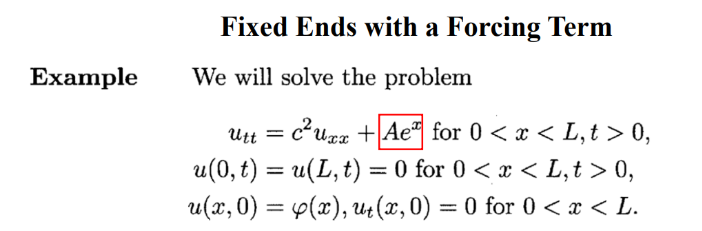

clear
clf
syms x c v(x) A L
assume(L,"positive")
SteadyS = c^2*diff(v,x,2)+A*exp(x) == 0

$$SteadyS(x) = c^{2}\,\frac{\partial^{2}}{\partial x^{2}}v\left(x\right)+A\,{\mathrm{e}}^{x}=0$$

C0 = v(0) == 0

$$C0 = v\left(0\right)=0$$

CL = v(L) == 9

$$CL = v\left(L\right)=9$$

vg(x) = dsolve(SteadyS)

$$vg(x) = C_{2}+C_{1}\,x-\frac{A\,{\mathrm{e}}^{x}}{c^{2}}$$

v(x) = collect(dsolve(SteadyS,[C0 CL]),[x,exp(x)])

$$v(x) = \frac{9\,c^{2}-A+A\,{\mathrm{e}}^{L}}{L\,c^{2}}\,x+\left(-\frac{A}{c^{2}}\right)\,{\mathrm{e}}^{x}+\frac{A}{c^{2}}$$

**Transient w(x,t) = u(x,t) - v(x)**

**Separation part**

syms t w(x,t) phi(x)
assume([L c],"positive")
WaveEq = c^2*diff(w,x,2) == diff(w,t,2)

$$WaveEq(x, t) = c^{2}\,\frac{\partial^{2}}{\partial x^{2}}w\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}w\left(x,t\right)$$

BC0 = w(0,t) == 0;BCL = w(L,t) == 0;
t0 = w(x,0) == phi(x) - v(x)

$$t0 = w\left(x,0\right)=\varphi \left(x\right)-\frac{A}{c^{2}}+\frac{A\,{\mathrm{e}}^{x}}{c^{2}}-\frac{x\,\left(9\,c^{2}-A+A\,{\mathrm{e}}^{L}\right)}{L\,c^{2}}$$

Dt = diff(w,t);
Dt0 = Dt(x,0) == 0

$$Dt0 = \left({\left(\frac{\partial }{\partial t}w\left(x,t\right)\right)|}_{t=0}\right)=0$$

syms T(t) X(x)
SepVar  = subs(WaveEq,w(x,t),X(x)*T(t));
BC0 = subs(BC0,w(0,t),X(0))

$$BC0 = X\left(0\right)=0$$

BCL = subs(BCL,w(L,t),X(L))

$$BCL = X\left(L\right)=0$$

T0 = subs(t0,w(x,0),T(0))

$$T0 = T\left(0\right)=\varphi \left(x\right)-\frac{A}{c^{2}}+\frac{A\,{\mathrm{e}}^{x}}{c^{2}}-\frac{x\,\left(9\,c^{2}-A+A\,{\mathrm{e}}^{L}\right)}{L\,c^{2}}$$

DT = diff(T,t);
DT0 = subs(Dt0,Dt(x,0),DT(0))

$$DT0 = \left({\left(\frac{\partial }{\partial t}T\left(t\right)\right)|}_{t=0}\right)=0$$

SepVar = SepVar/(X(x)*T(t))

$$SepVar(x, t) = \frac{c^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}$$

syms lambda
assume(lambda,"positive")
var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{c^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqT = var(2) == -lambda^2

$$eqT = \frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}=-\lambda^{2}$$

X(x) = dsolve(eqX,BC0)

$$X(x) = -C_{1}\,\sin\left(\frac{\lambda \,x}{c}\right)$$

T(t) = dsolve(eqT,DT0)

$$T(t) = C_{1}\,\cos\left(\lambda \,t\right)$$

constantX = setdiff(symvar(X(x)),sym(['C', x, lambda, c]));
X(x) = subs(-X(x),constantX,sym('C2'))

$$X(x) = C_{2}\,\sin\left(\frac{\lambda \,x}{c}\right)$$

sln = X(L) == 0;
[lambda,parameter,~] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer", "positive"]);
lambda = subs(lambda,parameter,n)

$$lambda = \frac{\pi \,c\,n}{L}$$

syms A_n ustruct(x,t);
sT(t) = subs(T(t),str2sym({'lambda','C1'}),{lambda,A_n});
sX(x) = subs(X(x),str2sym({'lambda','C2'}),{lambda,1});
ustruct(x,t) = sX(x)*sT(t)

$$ustruct(x, t) = A_{n}\,\cos\left(\frac{\pi \,c\,n\,t}{L}\right)\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

**Fourier Series part**

syms Sigma
f0 = ustruct(x,0)

$$f0 = A_{n}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

f0 = subs(f0,sym('A_n'),1);
A_n = 2/L*int(rhs(T0)*f0,x,[0 L])

$$A\_n = \frac{2\,\int_{0}^{L}\sin\left(\frac{\pi \,n\,x}{L}\right)\,\left(\varphi \left(x\right)-\frac{A}{c^{2}}+\frac{A\,{\mathrm{e}}^{x}}{c^{2}}-\frac{x\,\left(9\,c^{2}-A+A\,{\mathrm{e}}^{L}\right)}{L\,c^{2}}\right)\mathrm{d}x}{L}$$

w = subs(ustruct,'A_n',Sigma)*A_n

$$w(x, t) = \frac{2\,\Sigma \,\cos\left(\frac{\pi \,c\,n\,t}{L}\right)\,\sin\left(\frac{\pi \,n\,x}{L}\right)\,\int_{0}^{L}\sin\left(\frac{\pi \,n\,x}{L}\right)\,\left(\varphi \left(x\right)-\frac{A}{c^{2}}+\frac{A\,{\mathrm{e}}^{x}}{c^{2}}-\frac{x\,\left(9\,c^{2}-A+A\,{\mathrm{e}}^{L}\right)}{L\,c^{2}}\right)\mathrm{d}x}{L}$$

v(x,t) = v;
waveSol = sym('w') + v

$$waveSol(x, t) = w+\frac{9\,c^{2}-A+A\,{\mathrm{e}}^{L}}{L\,c^{2}}\,x+\frac{A}{c^{2}}+\left(-\frac{A}{c^{2}}\right)\,{\mathrm{e}}^{x}$$